# Load data:

ds = dolfyn_read('data/dolfyn/Sig500_Echo.ad2cp');

Reading file data/dolfyn/Sig500_Echo.ad2cp


%ds = dolfyn_read('data/dolfyn/Sig500_Echo.ad2cp','nens',15000);

To see whats in the dataset, it is recommended that users open the ds variable in the workspace. Alternatively, removing the semicolon in the above line will print the connents of ds. 

## First Steps and Cleaning Data

### 1) See uncleaned data

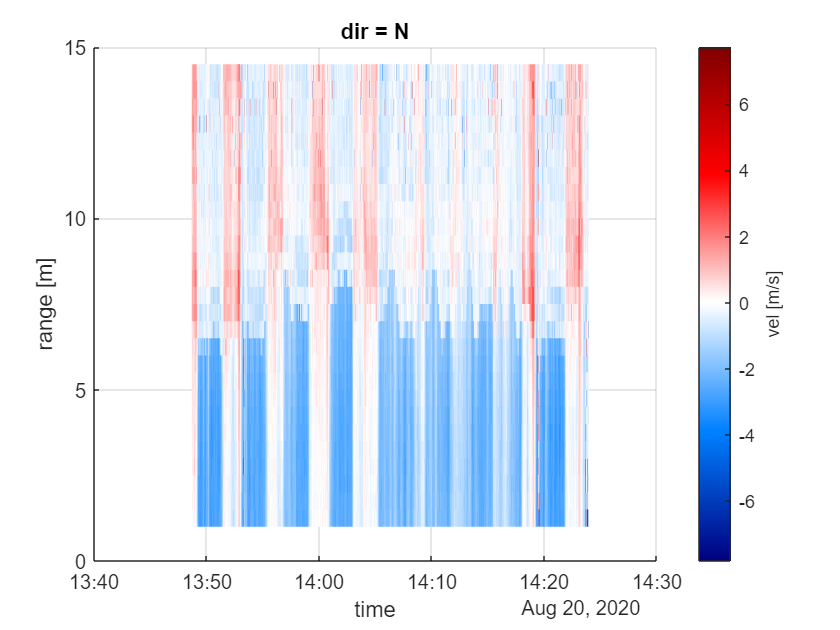

dolfyn_plot(ds,'vel','dim',2)

### 2) Clean data

Make a copy of ds to compare changes to. Also tally all the nans in the velocity data of ds (since that's what we're adjusting)

%now to clean with new functions
cleands = ds;
numnans = sum(squeeze(sum(squeeze(isnan(cleands.vel.data)))))

numnans =      0     0     0     0


Call val_exceeds_thresh first, this fills in a lot of nans in vel.data as shown below

cleands.vel = val_exceeds_thresh(cleands.vel, thresh = 3.0);
numnans = sum(squeeze(sum(squeeze(isnan(cleands.vel.data)))))

numnans =    245   594    36     6


Now to plot the data with the nans. Nans are displayed with the background color in the plot (white)

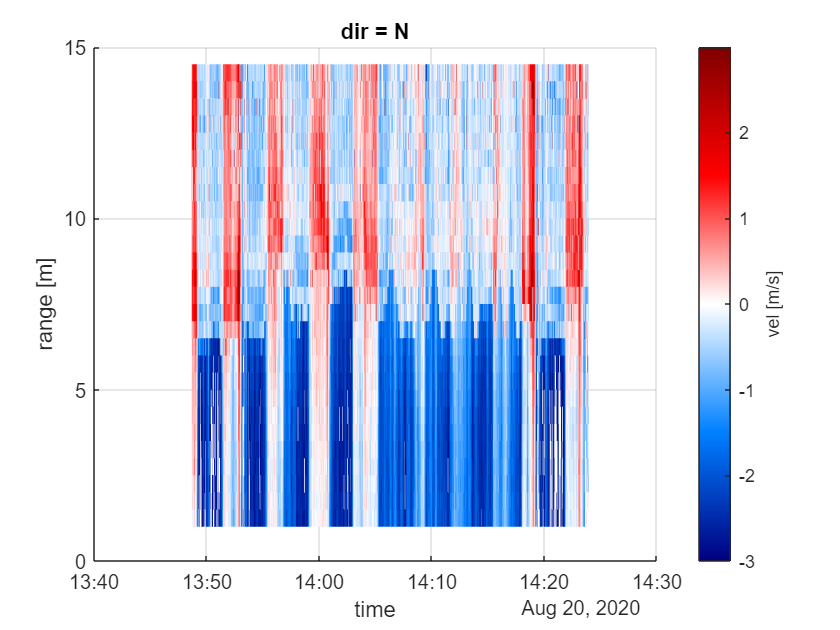

dolfyn_plot(cleands,'vel','dim',2)

Now we fill in the gaps (nans) by interpolating over time

cleands.vel = fillgaps_time(cleands.vel);
numnans = sum(squeeze(sum(squeeze(isnan(cleands.vel.data)))))

numnans =      0     0     0     0


Notice the nans have been replaced with numeric values.

Now plot the new cleaned velocity with filled gaps. It is different now :)

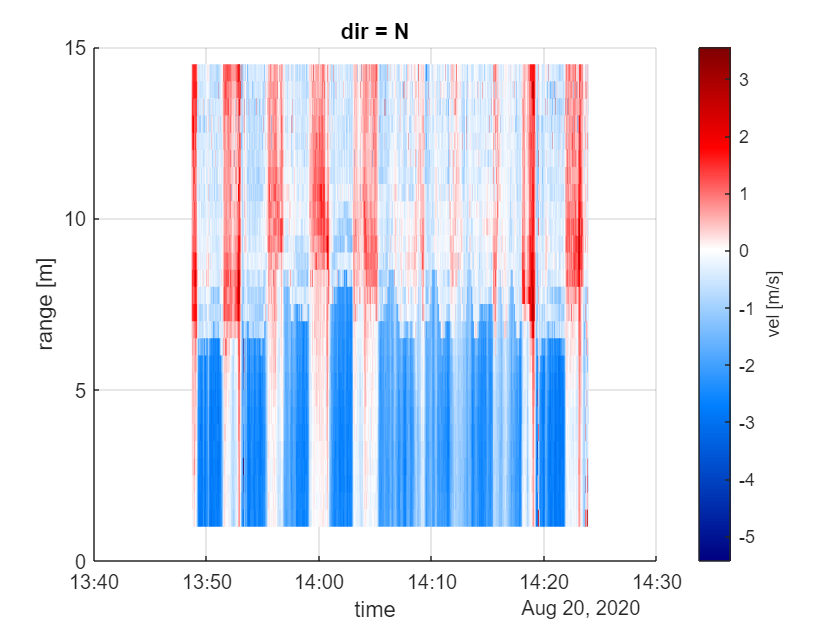

dolfyn_plot(cleands,'vel','dim',2)

There's no more nans to fill in gaps for, but

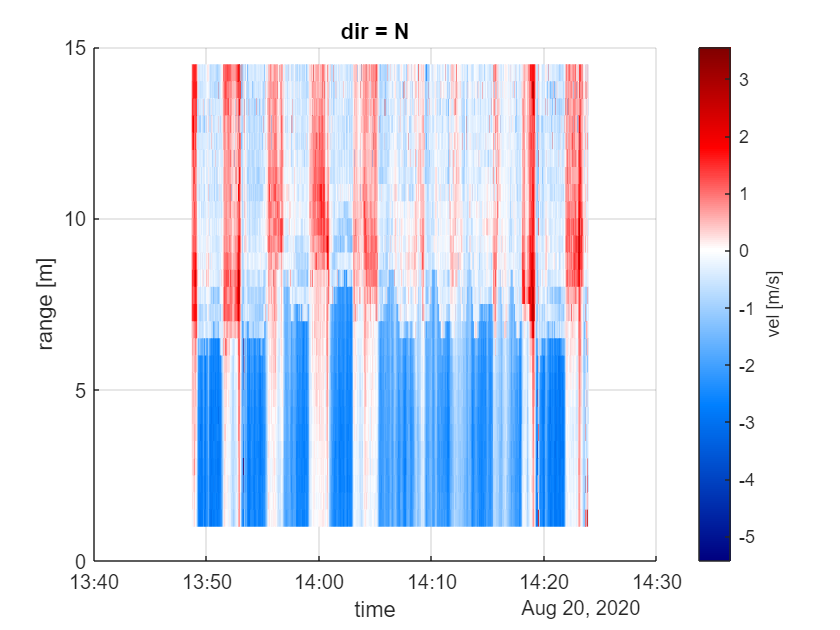

cleands.vel = fillgaps_depth(cleands.vel);
dolfyn_plot(cleands,'vel','dim',2)

## Saving and Loading Dolfyn datasets

Datasets can be saved and loaded using the write_netcdf and read_netcdf functions, respectively. 

% Uncomment these lines to save and load to your current working directory
write_netcdf(cleands, 'your_data.nc');
% ds_saved = read_netcdf('your_data.nc');